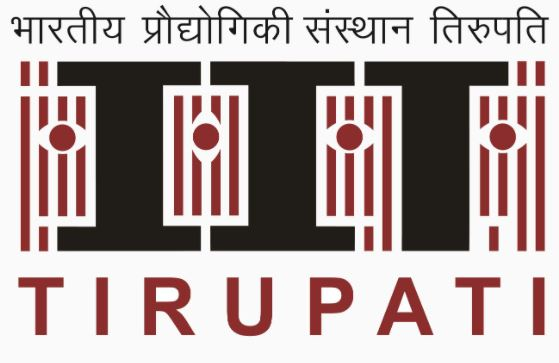

### **Digital Signal Processing Laboratory**

**LabSheet-04**

Name: Suriyaa MM

Roll Number: EE23B054

**A. Observation of Gibbs Phenomenon**

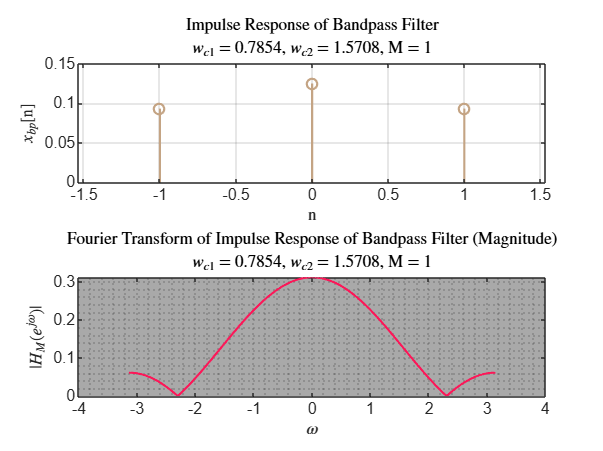

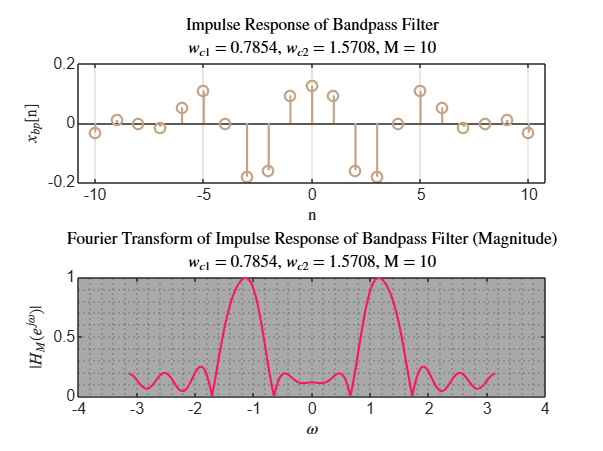

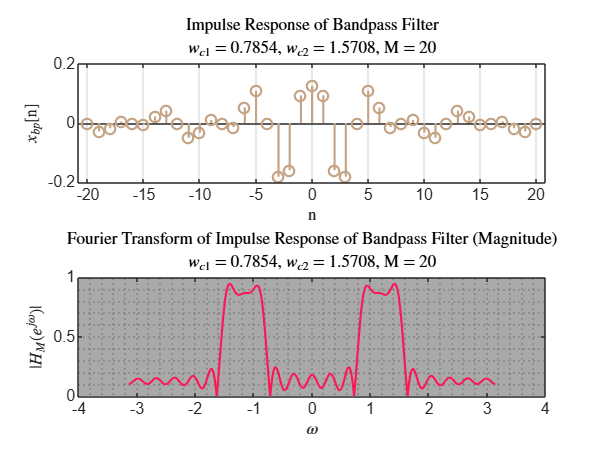

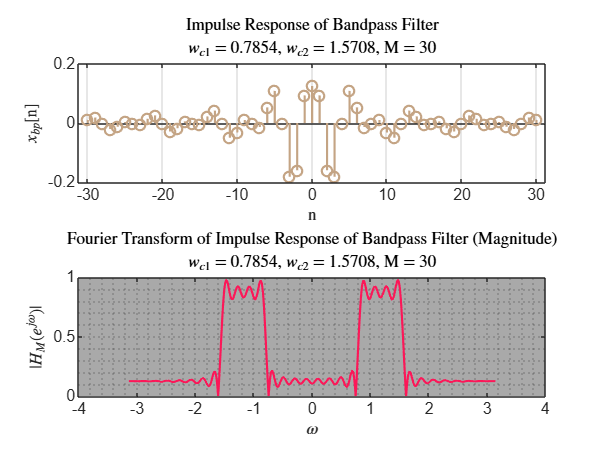

COLOUR_BROWN    = "#c4a484";
COLOUR_RED      = "#fc1758";
COLOUR_BLUE     = "#4a8af0";
COLOUR_GREY     = "#A9A9A9";

% Fix values of w_c and the bandwidth
w_c1 = pi / 4; % Lower cutoff frequency
w_c2 = pi / 2; % Upper cutoff frequency

for M = [1, 10, 20, 30]
   
   % Generate the impulse response of the bandpass filter
    hbp = zeros(1, 2*M+1);
    for n = -M:M
        if n == 0
            hbp(n+M+1) = (w_c2 - w_c1) / (2*pi);
        else
            hbp(n+M+1) = (sin(w_c2*n) - sin(w_c1*n)) / (pi*n);
        end
    end

    n = -M:M;

    % Define the frequency range for w
    deltaw = 10e-7;
    w = -pi:deltaw:pi;

    % Compute the Fourier Transform Hm(e^jw) of hbp
    Hm = fftshift(fft(hbp, length(w)));

    figure;
    figProps = gcf;
    figProps.Position(3:4) = figProps.Position(3:4) * 3;

    % Plot hbp
    subplot(2,1,1);
    stem(n, hbp, Color = COLOUR_BROWN, LineWidth = 1.25);
    xlabel('n', Interpreter = "latex");
    ylabel('$x_{bp}$[n]', Interpreter = "latex");
    title('Impulse Response of Bandpass Filter', Interpreter = "latex");
    subtitle(['$w_{c1}$ = ' num2str(w_c1) ', $w_{c2}$ = ' num2str(w_c2) ', M = ' num2str(M)], Interpreter = "latex");
    grid on;

    % Plot Fourier Transform of hbp
    subplot(2,1,2);
    plot(w, abs(Hm), Color = COLOUR_RED, LineWidth=1.25);
    xlabel('$\omega$', Interpreter = "latex");
    ylabel('|$H_{M}(e^{j\omega})$|', Interpreter = "latex");
    title('Fourier Transform of Impulse Response of Bandpass Filter (Magnitude)', Interpreter = "latex");
    subtitle(['$w_{c1}$ = ' num2str(w_c1) ', $w_{c2}$ = ' num2str(w_c2) ', M = ' num2str(M)], Interpreter = "latex");

    set(gca, "XMinorGrid", "on");
    set(gca, "YMinorGrid", "on");
    set(gca, "Color", "#A9A9A9");

end

**Gibbs phenomenon**

- Occurs when approximating a discontinuous function using a finite number of Fourier series terms.

- The oscillations near the cutoff frequency are due to the truncation of the ideal sinc function. These oscillations do not diminish with increasing `M` but instead approach a fixed percentage of the discontinuity height.

**In Plot **$$H_{M}(e ^ {j \omega})$ vs $\omega$$ 

- The magnitude of the Fourier Transform $$H_{M}(e ^ {j \omega})$ should show a bandpass characteristic, with high values at included frequencies $[-\frac{\pi}{2}, -\frac{\pi}{4}], [\frac{\pi}{4}, \frac{\pi}{2}]$ and attenuated values at other frequencies.

#### B. Generation of Random Sinusoid

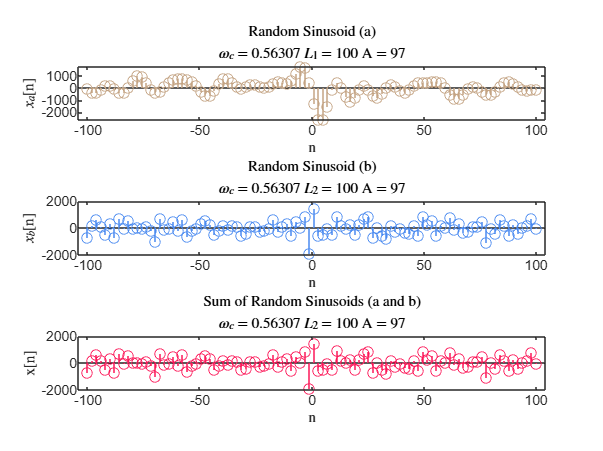

% Fix a value of w_c
w_c = pi * rand();
% Fix a value of L1
L1 = 100;
% Fix a value of A between 1 and 100
A = randi(100);
% Fix a value of N between 1 and 100 and generate n <= N
N = 100;
n = linspace(-N, N, L1);

% Generation of discerete w in range [0, w_c] which is an Linear array of size L1
w = w_c * rand(1, L1);

% Generation of discerte A in range [1, A] which is a Linear array of size L1
a = 1 + A * rand(1, L1);

% Generation of discrete phi in range [-pi, pi] which is a Linear array of size L1
phi = 2*pi + pi * rand(1, L1);

% Initialize the signal x_a[n]
x_a = zeros(size(n));

% Construct the signal
for i = 1:L1
    x_a = x_a + a(i) * cos(w(i) * n + phi(i)); % Summing the contributions
end

figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 3;

subplot(3,1,1);
stem(n, x_a, Color = COLOUR_BROWN);
xlabel('n', Interpreter = "latex");
ylabel('$x_a$[n]', Interpreter = "latex");
title('Random Sinusoid (a)', Interpreter = "latex");
subtitle(['$\omega _c$ = ' num2str(w_c) ' $L_1$ = ' num2str(L1) ' A = ' num2str(A)], Interpreter = "latex");

% Fix a value of L2
L2 = 100;
% generate n <= N
n = linspace(-N, N, L2);

% Generation of discerete w in range [w_c, pi] which is an Linear array of size L2
w = (pi - w_c) + pi * rand(1, L1);

% Generation of discerte A in range [1, A] which is a Linear array of size L1
a = 1 + A * rand(1, L2);

% Generation of discrete phi in range [-pi, pi] which is a Linear array of size L1
phi = 2*pi + pi * rand(1, L2);

% Initialize the signal x_a[n]
x_b = zeros(size(n));

% Construct the signal
for i = 1:L2
    x_b = x_b + a(i) * cos(w(i) * n + phi(i)); % Summing the contributions
end

subplot(3,1,2);
stem(n, x_b, Color = COLOUR_BLUE);
xlabel('n', Interpreter = "latex");
ylabel('$x_b$[n]', Interpreter = "latex");
title('Random Sinusoid (b)', Interpreter = "latex");
subtitle(['$\omega _c$ = ' num2str(w_c) ' $L_2$ = ' num2str(L2) ' A = ' num2str(A)], Interpreter = "latex");


x_n = x_a + x_b;
subplot(3,1,3);
stem(n, x_b, Color = COLOUR_RED);
xlabel('n', Interpreter = "latex");
ylabel('x[n]', Interpreter = "latex");
title('Sum of Random Sinusoids (a and b)', Interpreter = "latex");
subtitle(['$\omega _c$ = ' num2str(w_c) ' $L_2$ = ' num2str(L2) ' A = ' num2str(A)], Interpreter = "latex");

#### C. Filling x[n] using Truncated BPF

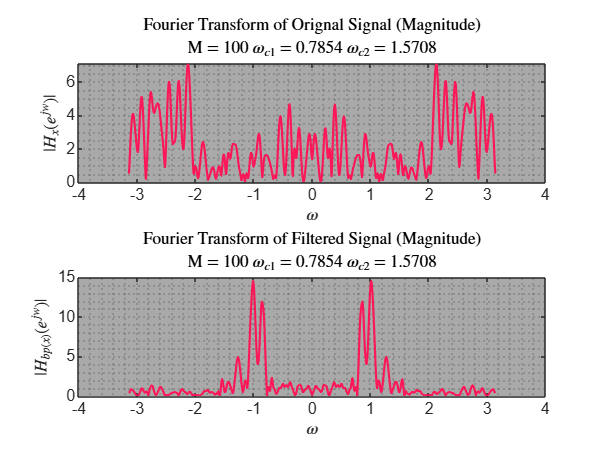

% Define parameters
M = 100; % Length of the impulse response
wc1 = pi/4; % Lower cutoff frequency
wc2 = pi/2; % Upper cutoff frequency

% Generate the impulse response of the bandpass filter
hbp = zeros(1, 2*M+1);
for n = -M:M
    if n == 0
        hbp(n+M+1) = (wc2 - wc1) / (2*pi);
    else
        hbp(n+M+1) = (sin(wc2*n) - sin(wc1*n)) / (pi*n);
    end
end

ybp = conv(x_n, hbp);

figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 2;

w = -pi:0.0001:pi;

% Plot Magnitude of Frequency Response of x
subplot(2,1,1);
plot(w,abs(fftshift(fft(x_n/max(abs(x_n)), length(w)), length(w))), Color = COLOUR_RED, LineWidth = 1.25);
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('|$H_{x}( e^{jw} )$|', 'Interpreter', 'latex');
title('Fourier Transform of Orignal Signal (Magnitude)', 'Interpreter', 'latex');
subtitle(['M = ' num2str(M), ' $\omega _{c1}$ = ' num2str(wc1), ' $\omega _{c2}$ = ' num2str(wc2)], 'Interpreter', 'latex');
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");
set(gca, "Color", "#A9A9A9");

% Plot Magnitude of Frequency Response of ybp
subplot(2,1,2);
plot(w,abs(fftshift(fft(ybp/max(abs(ybp)), length(w)))), Color = COLOUR_RED, LineWidth = 1.25);
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('|$H_{bp(x)}( e^{jw} )$|', 'Interpreter', 'latex');
title('Fourier Transform of Filtered Signal (Magnitude)', 'Interpreter', 'latex');
subtitle(['M = ' num2str(M), ' $\omega _{c1}$ = ' num2str(wc1), ' $\omega _{c2}$ = ' num2str(wc2)], 'Interpreter', 'latex');
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");
set(gca, "Color", "#A9A9A9");

**Bandpass Filter**

A bandpass filter is a type of electronic filter that allows a specific range of frequencies to pass through while attenuating frequencies outside that

range. It is essentially a combination of a low-pass filter and a high-pass filter

**Observations:**

- **Original Signal:** The Fourier transform $(H_{x}( e^{jw} ))$ of the original signal $(x[n])$ shows its frequency components

- **Filtered Signal:** The Fourier transform $(H_{bp(x)}( e^{jw} ))$ of the filtered signal $(ybp)$ shows the frequency components that have passed through the bandpass filter.

- **Bandpass Effect:** The magnitude of the Fourier transform of $(ybp)$ is significantly higher within the passband compared to the magnitude of the Fourier transform of $(x[n])$ outside the passband. Thus we can see that our bandpass filter is working correctly.